clear 
close all

%%%%%%%%%%%%%%%%%%%%%%% create dataset %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%presets for dataset
range = 3000;
datapoints = 1000;

x = randn() + randi(2*range,datapoints,1)-range;
y = randn() + randi(2*range,datapoints,1)-range;

%plot desired border classification splitter line
aDesired = 20;
bDesired = 3000;
yDesired = @(xDesired) aDesired.*xDesired + bDesired;
plot([-range range],[yDesired(-range) yDesired(range)],'k')
hold on

%create colormap according to position relative to the desired line
c = zeros(length(x),3);
for h = 1:length(x)
    if (yDesired(x(h)) - y(h)) < 0
        c(h,:) = [1,0,0];
    else
        c(h,:) = [0,0,1];
    end
end
scatter(x,y,[],c,'filled')
axis([-range range -range range])
%%%%%%%%%%%%%%%%%%%%%%% create perceptron %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%initialise bias and weights 
weights = randn(1,3);
bias = 1;
%%%%%%%%%%%%%%%%%%%%%%% train perceptron %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%get labeled data for training
true_output = ((yDesired(x) - y)<0)*2 - 1; 

%set learn parameters
Iterations = 500;
lern_rates = [0.00005,0.00005,5];

tic
for i = 1:Iterations
    for j = 1:length(x)

        inputs = [x(j);y(j);bias];
        guess = tanh(weights*inputs);  
        error = true_output(j) - guess;

        %learn "optimisation loop
        if error~=0
            weights = weights + inputs' .* error .* lern_rates;
        end
    end
    %plot best line of each iteration in yellow
    maxY = ( - weights(1)*max(x) - weights(3)*bias)/weights(2);
    minY = ( - weights(1)*min(x) - weights(3)*bias)/weights(2);
    plot([min(x),max(x)],[minY, maxY],'y')
end
toc

Elapsed time is 0.387298 seconds.


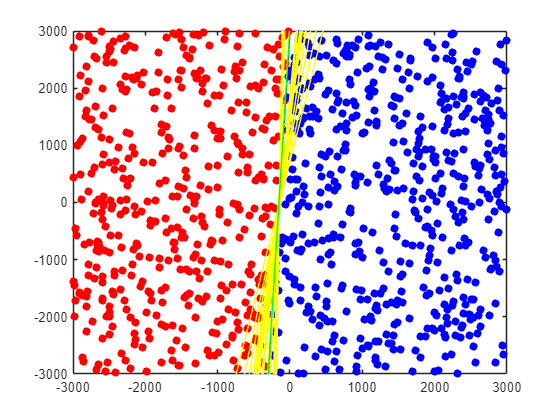


%plot best separation line in green
maxY = ( - weights(1)*max(x) - weights(3)*bias)/weights(2);
minY = ( - weights(1)*min(x) - weights(3)*bias)/weights(2);
plot([min(x),max(x)],[minY, maxY],'g')


weights

weights =    -2.4393    0.1213 -371.7745
